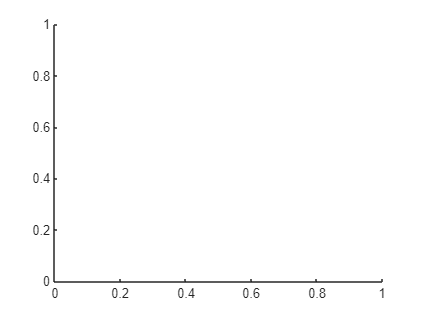

% Новые вычисления
clear all
%fpass = [0.0001,2.5];
fpass=3;
hold off

NAMES = ["2025-04-11"];
ldf_fl = ones(length(NAMES));%ЛДФ есть
for m = 1:length(NAMES)
NAME = convertStringsToChars(NAMES(m)); %Название папки с данными
[rho_skin, base_imp] = import_model(strcat('DATA/',NAME,'/model_res.txt'), [6, Inf]);
res = coeffvalues(fit(rho_skin,base_imp,'poly1'));
%Чтение файла расписания процедуры
TT = importtt(strcat('DATA/',NAME,'/TIMETABLE.xlsx'),NAME);

% Чтение исходных данных циклов

    load(strcat('OUT/',NAME,'/CYCLE_DATA.mat'));

try
    load(strcat('OUT/',NAME,'/DATA_LDF.mat'));
catch ME
    ldf_fl(m) = 0;
end
N = length(TT.DATE);
dV = zeros(N-1,1);
means_dV = zeros(N-1,1);
std_dV = zeros(N-1,1);

for i = 1:N
    if (i ~= 4)
    if i == N
        size{m}(i) = 0;
        if (ldf_fl(m))
            temp_ldf = lowpass(DATA_LDF.MC(find(DATA_LDF.DATE_LDF>TT.DATE(i)& (abs(DATA_LDF.MC) < 50))),fpass,20);
            %means_ldf(i) = mean(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20));
            means_ldf(i) = mean(temp_ldf);
            %std_dev_ldf (i) = std(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20));
            std_dev_ldf (i) = std(temp_ldf);
        end
        clear Data_cycle;
        for j = 1:length(CYCLE_DATA)
            idx = 1;
            if (CYCLE_DATA{j}.NAME > TT.DATE(i))
                Data_cycle{idx} = CYCLE_DATA{j};
                size{m}(i) = size{m}(i)+length(Data_cycle{idx});
                idx = idx+1;
            end
        end
        
        [Amp1,t_Amp1,Amp2,t_Amp2,d_Amp1,t_dAmp1,d_Amp2,t_dAmp2,dRHEO1,Tlvet,Z_Tlvet,T,dZ,dV(i)] = params_new(Data_cycle,res(1),res(2));
        
        
        means_dV(i) = mean(dV);
        std_dV(i) = std(dV);
    else
        size{m}(i) = 0;
        if (ldf_fl(m))
            temp_ldf = lowpass(DATA_LDF.MC(find(DATA_LDF.DATE_LDF>TT.DATE(i)& (abs(DATA_LDF.MC) < 50))),fpass,20);
            %means_ldf(i) = mean(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20));
            means_ldf(i) = mean(temp_ldf);
            std_dev_ldf (i) = std(temp_ldf);
            %std_dev_ldf (i) = std(movmax(temp_ldf(abs(temp_ldf)<2),20)-movmin(temp_ldf(abs(temp_ldf)<2),20));
        end
        clear Data_cycle;
        for j = 1:length(CYCLE_DATA)
            idx = 1;
            if (CYCLE_DATA{j}.NAME < TT.DATE(i+1) && (CYCLE_DATA{j}.NAME > TT.DATE(i)))
                Data_cycle{idx} = CYCLE_DATA{j};
                size{m}(i) = size{m}(i)+length(Data_cycle{idx});
                idx = idx+1;
            end
        end   
            
        
        [Amp1,t_Amp1,Amp2,t_Amp2,d_Amp1,t_dAmp1,d_Amp2,t_dAmp2,dRHEO1,Tlvet,Z_Tlvet,T,dZ,dV(i)] = params_new(Data_cycle,res(1),res(2));
        
        means_dV(i) = mean(dV);
        
        std_dV(i) = std(dV);
        
    
    end
    end
end


if (length(means_dV) >= 4)
    means_dV(4) = [];
    std_dV(4) = [];
    if(ldf_fl(m))
        means_ldf(4) = [];
        std_dev_ldf(4) = [];
    end
end
if(ldf_fl(m))
    DATA_Means_ldf{m} = means_ldf;
    DATA_std_ldf{m} = std_dev_ldf;
end
dV_mean{m} = means_dV;
dV_std{m} = std_dV;
end

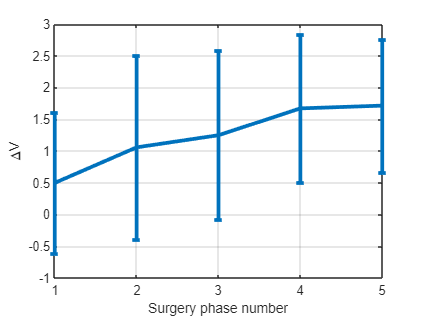

x = 1:5;
errorbar(x,means_dV,std_dV,LineWidth = 3);
xlabel("Surgery phase number");
ylabel("\DeltaV");
grid on

ldf = DATA_LDF.MC;
time_ldf = DATA_LDF.TIME_LDF;

plot(ldf_Copy)